# Rectangular resonator

Here, we will take a look at the eigenvalues of a rectangular resonator. 

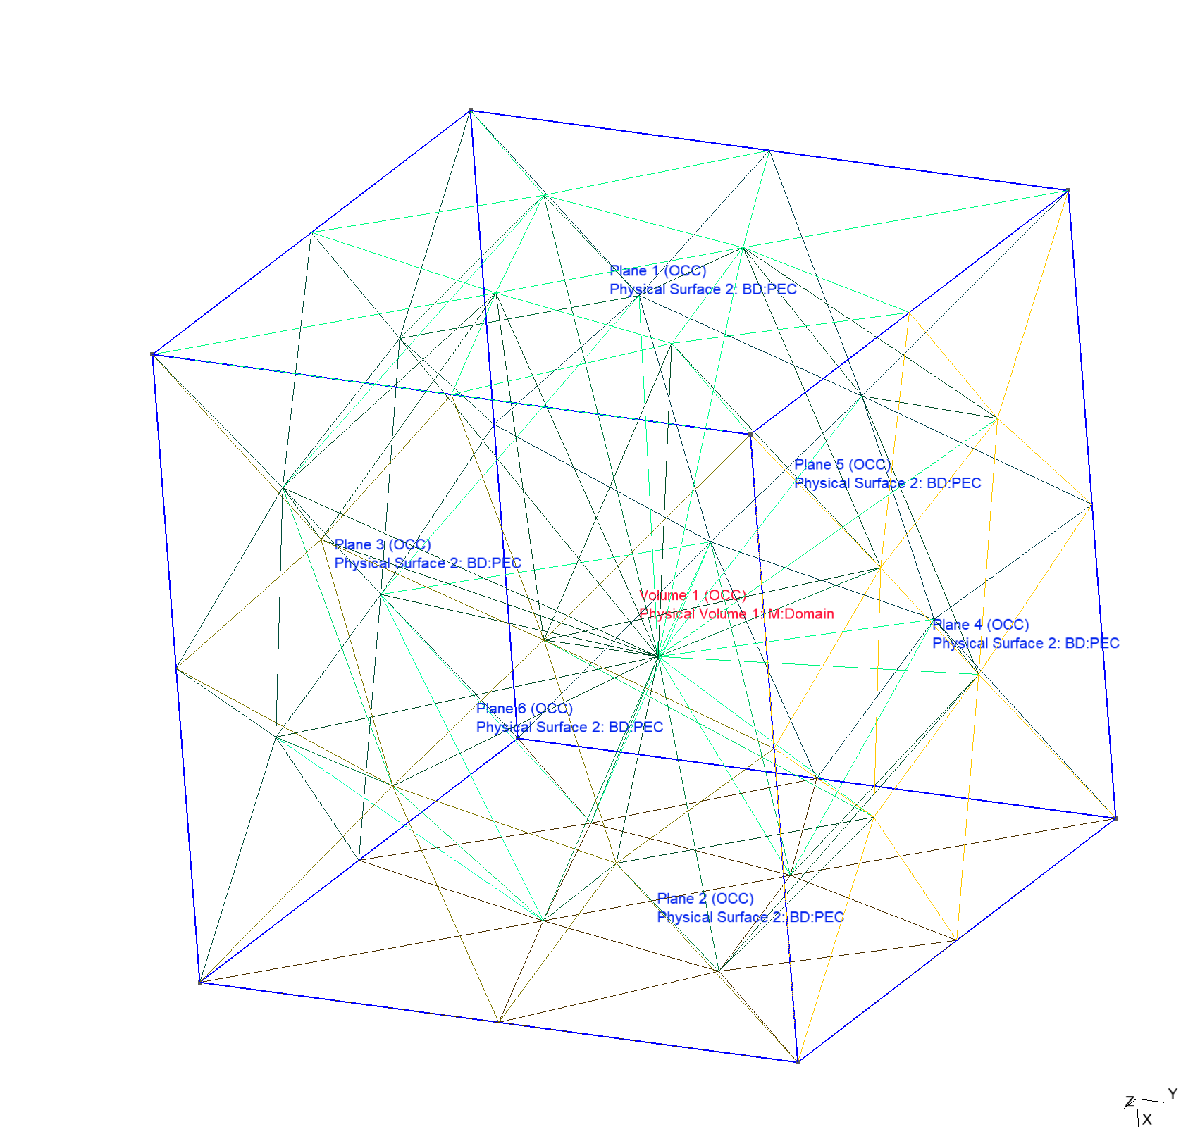

The image shows the used mesh. It has only one interior point. A mesh without any interior points can and most likely will break the simulation. By default the side length' $a,b,c=\pi$ this can be changed in the geo file. What we are interested in is the solution of 

## 	
$$S\vec x = \lambda M \vec x$$


for the eigenvalues $\lambda$ and the eigenvectors $\vec x$. We start by setting up the problem as usual:

close all;
clear;

file = 'rect';

mesh = ofem_v2.Geometry;
mesh.load_from_msh(file);

mesh.reorderAC;
mesh.create_faces;
mesh.create_edges;
mesh.connectFa2Ed;
mesh.jacobiandata;

fe = ofem_v2.elements.loadFE('HCurl_3D_Order_2');

dofs = ofem_v2.DOFHandler(mesh);
dofs.attach(fe);

We choose one as material parameter for the stiffness matrix as well as the mass matrix. Here, we are interested in $\lambda = k^2 = m^2+n^2+p^2$ . So $\varepsilon, \mu$ and the frequency are stuffed in $\lambda$.

air = ofem_v2.materials.Material;
air.stiff = 1;
air.mass = 1;

mesh.setMaterial('Domain',air);

PEC = ofem_v2.boundary.DirichletEdge([0;0;0],'PEC',mesh);

resonator = ofem_v2.Physical_Problem(fe,mesh,1,1,0);

resonator.setParaS('stiff');
resonator.setParaM('mass');

PEC on all boundaries (metallic resonator)

resonator.setBoundaryCondition(PEC);

resonator.attachDOFHandler(dofs);
dofs.generateDOFs;

resonator.assemble;

To avoid the nullspace of the curl operator we assemble another system for the H1 problem. For this we require $Y_g$ the discrete divergence operator and $Y_g^T$ the discrete gradient operator. Using this we apply the iterate to the H1 problem and take the divergence of the result. This is then subtracted from the solution. By doing so we explicitly move the solution to a space orthogonal to the divergence.

## 
$$\vec x = \vec x -Y_g\left(Y_g^TMY_g\right)^{-1}\left(\left(MY_g\right)^T\vec x\right)$$


Algorithmic not mathematic! Here, $Y_g^TMY_g$ represents the H1 stiffness matrix. the right parenthesis map the current iterate to the H1 space and the operator on the left maps it back to the Hcurl space using the divergence.

Y_g = fe.AMS(resonator);
amsDOFS = dofs.AMSDOFs(resonator);

S = resonator.S;
M = resonator.M;

x = resonator.u;

As we use a block method later, we generate some random vectors here. The amount of vectors should always be lower than the number of dofs in the HCurl problem. (total dofs - dirichlet dofs that is)

X = randn(length(x),20);
x = zeros(size(X));

For the H1 problem we also need to apply homogeneous Dirichlet boundary conditions. This is done using the asm dofs. Currently the S_g computed by AMS is broken and we need to recompute it.

Y_g = Y_g(:,amsDOFS);
S_g = Y_g'*M*Y_g;

To actually solve the eigenvalue problem we use an LOBPCG method with nullspace projection. The parameters we require are as follow:

**Input:**

- X: random generated first guess vectors with dim(x,2) < dofs

- S: stiffness matrix of HCurl

- M: mass matrix of HCurl

- C: preconditioner for HCurl, currently unused, just pass []

- n: the number of eigenvectors we want to converge, generally half of dim(x,2) up to dim(x,2)

- it: max iterations

- tol: tolerance of convergence

- Y_g: discrete divergence operator

- S_g: manufactured stiffness matrix of H1 problem

- dofs: the dofs of HCurl

**Output:**

- x: resulting eigenvectors

- l: resulting eigenvalues

- Wn: residuals for each iteration

- lh: eigenvalues of each iteration

tic
[x(dofs.freeDOFs,:),l,Wn,lh] = ofem_v2.solvers.lobpcgModProj(X,S,M,[],10,50,1e-9,Y_g,S_g,dofs.freeDOFs);

Eig 1 converged at iteration 9
removing from pool
Eig 2 converged at iteration 9
removing from pool
Eig 3 converged at iteration 9
removing from pool
Eig 4 converged at iteration 11
removing from pool
Eig 5 converged at iteration 11
removing from pool
Eig 6 converged at iteration 14
removing from pool
Eig 7 converged at iteration 14
removing from pool
Eig 8 converged at iteration 14
removing from pool
Eig 9 converged at iteration 14
removing from pool
Eig 10 converged at iteration 14
removing from pool
converged!


toc

Elapsed time is 14.665777 seconds.


l

l =     2.0001
    2.0001
    2.0001
    3.0004
    3.0004
    5.0018
    5.0018
    5.0019
    5.0019
    5.0019


exact = [2,2,2,3,3,5,5,5,5,5,5,6,6,6,6,6,6,8,8,8]';
err = l-exact

err =     0.0001
    0.0001
    0.0001
    0.0004
    0.0004
    0.0018
    0.0018
    0.0019
    0.0019
    0.0019


tic
[x(dofs.freeDOFs,:),l,Wn,lh] = ofem_v2.solvers.lobpcgModProjlqsmin(X,S,M,[],10,50,1e-9,Y_g,S_g,dofs.freeDOFs);

Error using svd
SVD does not support sparse matrices. Use SVDS to compute a subset of the singular values and vectors of a sparse matrix.

Error in pinv (line 22)
[U, s, V] = svd(A, 'econ', 'vector');

Error in ofem_v2.solvers.lobpcgModProjlqsmin (line 32)
	dYMY

toc
l
exact = [2,2,2,3,3,5,5,5,5,5,5,6,6,6,6,6,6,8,8,8]';
err = l-exact

As lower order just don't have enough dofs in this setup, we need to choose at least 2nd order elements, even better 3rd order elements. For TE modes $p\neq 0$ and either $m$ or $n$ can be 0. For TM modes $m,n\neq 0$ and $p$ can be $0$. From $k^2=m^2+n^2+p^2$ we get TE: 2,2,3,5,5,6,6,6

and TM: 2,3,5,5,5,5,6,6,6,8,

for 2,2,2,3,3,5,5,5,5,5,5,6,6,6,6,6,6,8,8

l
exact = [2,2,2,3,3,5,5,5,5,5,5,6,6,6,6,6,6,8,8,8]';
err = l-exact

There is an error of atleast 1%. However, this is to expected for a mesh with only 100 tets and especially with only one interior node. 3rd order elements already give an error of less than 1e-3. Zeroth order falls through on the first try returning a zero eigenvalue. 1st order performs even worse, falling through on all compute eigenvalues. This is propably due to the explicit statement of gradients in the nedelec basis and the minimal amount of dofs in the H1 problem. All nodes except one are on the boundary. Higher orders remedy this problem by introducing edge, face and volume dofs for H1, aswell as HCurl. The fall through also seems to depend on the random vectors generated. For higher orders this does not occure. The result is the same, independent of the base.